clc; clear; close all;

%% Audio Signal Denoising via Hankel SVD

%% Step 1: Read the .wav file
[signal, fs] = audioread('input_voice.wav');

fprintf('Sample Rate : %d Hz\n', fs);

Sample Rate : 44100 Hz


fprintf('Total Samples : %d\n', length(signal));

Total Samples : 4940400


fprintf('Duration : %.2f seconds\n', length(signal)/fs);

Duration : 112.03 seconds



% Convert stereo to mono if needed
if size(signal, 2) == 2
    signal = mean(signal, 2);
    disp('Converted Stereo to Mono');
end

Converted Stereo to Mono



% Make it a row vector
signal = signal(:)';

% Remove DC offset
signal = signal - mean(signal);

% Normalize between -1 and +1
if max(abs(signal)) > 0
    signal = signal / max(abs(signal));
end

% Take only the first 5 seconds
duration_to_use = 5;
num_samples = duration_to_use * fs;
num_samples = min(num_samples, length(signal));

signal = signal(1:num_samples);
N = length(signal);

fprintf('Using first %.1f seconds = %d samples\n', duration_to_use, N);

Using first 5.0 seconds = 220500 samples


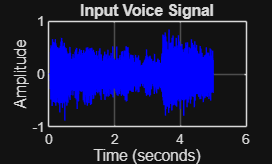


% Time vector after trimming
t = (0:N-1) / fs;

figure;
plot(t, signal, 'b', 'LineWidth', 0.6);
title('Input Voice Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;


%% Step 2: Build Hankel Matrix
L = min(1024, floor(N / 2));
K = N - L + 1;
H = zeros(L, K);

for j = 1:K
    H(:, j) = signal(j:j+L-1)';
end

fprintf('Hankel Matrix Size: %d x %d\n', L, K);

Hankel Matrix Size: 1024 x 219477


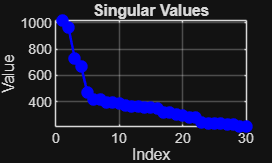


%% Step 3: Apply SVD
[U, S, V] = svd(H, 'econ');
singular_values = diag(S);

%% Step 4: Plot Singular Values
figure;
plot(singular_values(1:min(30, length(singular_values))), ...
    'bo-', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
title('Singular Values');
xlabel('Index');
ylabel('Value');
grid on;

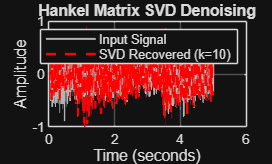


%% Step 5: Keep top-k and reconstruct Hankel matrix
k = 10;
S_k = S(1:k, 1:k);
H_clean = U(:, 1:k) * S_k * V(:, 1:k)';

%% Step 6: Convert Hankel matrix back to 1D signal
recovered = hankel_to_signal(H_clean);
recovered = recovered(1:N);
recovered = recovered / max(abs(recovered));

%% Step 7: Plot Results
figure;
plot(t, signal, 'Color', [0.7 0.7 0.7], ...
    'LineWidth', 1.2);
hold on;
plot(t, recovered, 'r--', 'LineWidth', 1.5);
legend('Input Signal', sprintf('SVD Recovered (k=%d)', k));
title('Hankel Matrix SVD Denoising');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

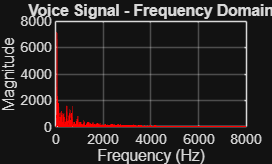


%% Step 8: Frequency Spectrum
f = (0:N-1) * (fs / N);
S_fft = abs(fft(signal));

figure;
plot(f(1:floor(N/2)), S_fft(1:floor(N/2)), ...
    'r', 'LineWidth', 0.8);
title('Voice Signal - Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 8000]);
grid on;


%% Step 9: Play and save denoised audio
disp('Playing denoised audio...');

Playing denoised audio...


sound(recovered, fs);

audiowrite('output_voice.wav', recovered', fs);
disp('Audio saved as output_voice.wav');

Audio saved as output_voice.wav



%% Helper Function
function recovered = hankel_to_signal(H_matrix)
    [L, K] = size(H_matrix);
    N = L + K - 1;

    result = zeros(1, N);
    counts = zeros(1, N);

    for i = 1:L
        for j = 1:K
            idx = i + j - 1;
            result(idx) = result(idx) + H_matrix(i, j);
            counts(idx) = counts(idx) + 1;
        end
    end

    recovered = result ./ counts;
end